# Setup

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

# K-Means


K = 10;               % number of clusters used
L = 200;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

orange = imread('orange.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h); 

tic
[ segm, ~ ] = kmeans_segm(orange, K, L, seed);

   123



toc

Elapsed time is 2.997087 seconds.


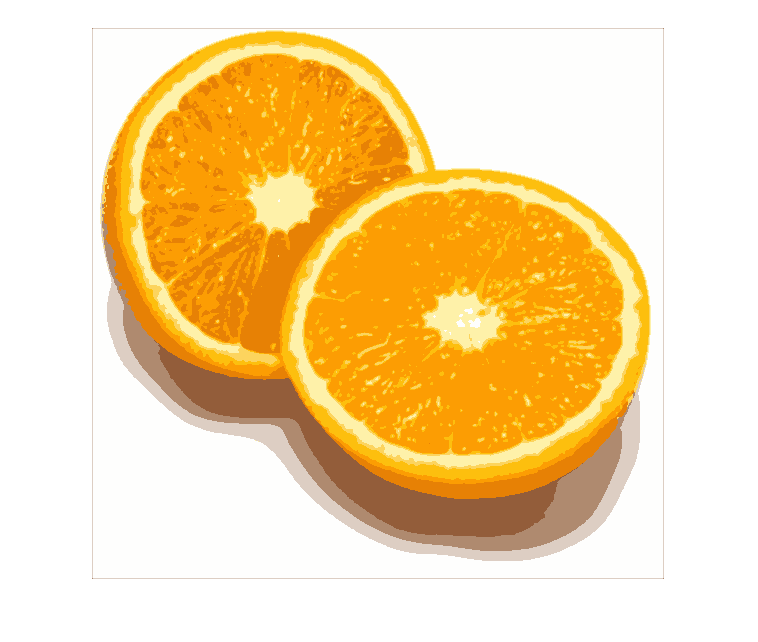

Inew = mean_segments(Iback, segm);
imshow(Inew);

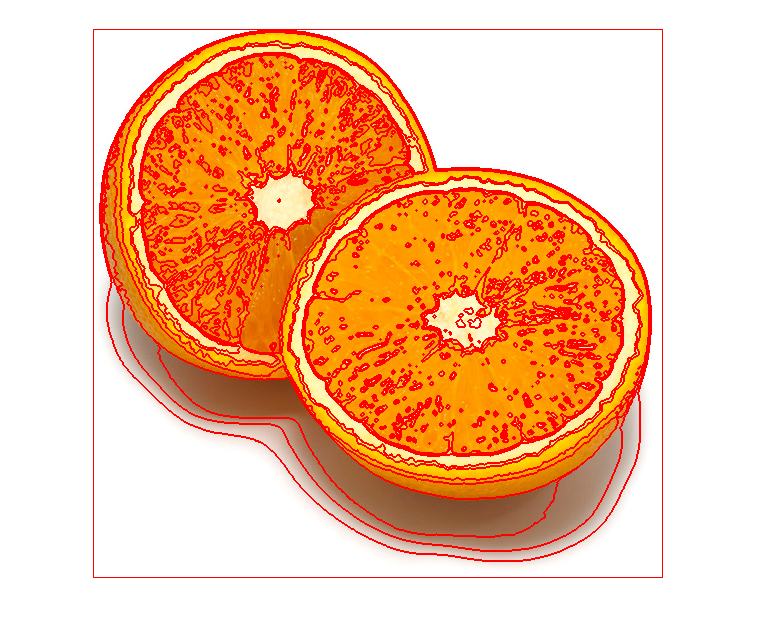

orange = overlay_bounds(Iback, segm);
imshow(orange);


K = 10;               % number of clusters used
L = 200;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 5.0;   % image preblurring scale

orange = imread('tiger2.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h);

[ segm, centers ] = kmeans_segm(orange, K, L, seed);

    61



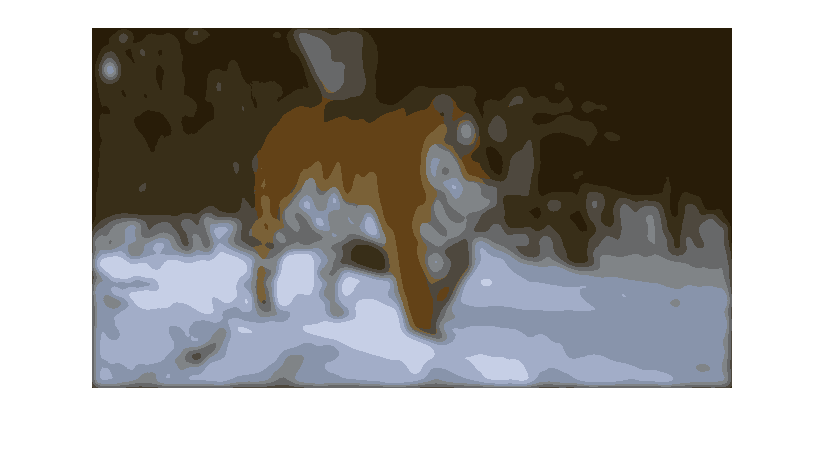


Inew = mean_segments(Iback, segm);
imshow(Inew);

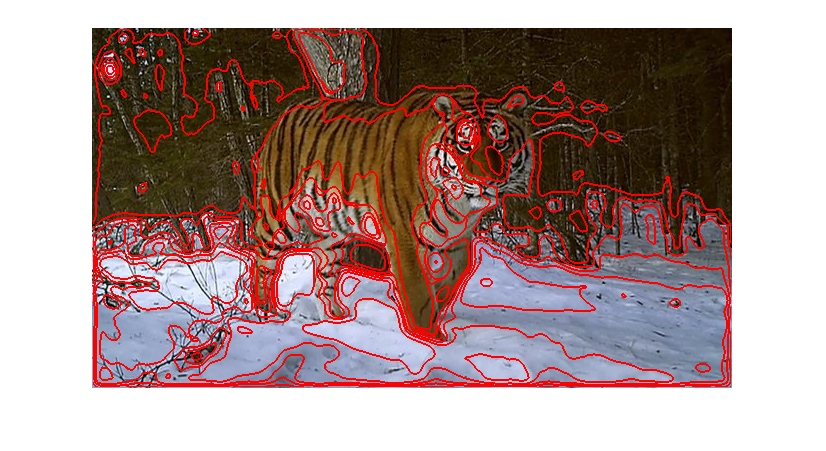

orange = overlay_bounds(Iback, segm);
imshow(orange);

# Mean Shift

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 12.0;  % spatial bandwidth
colour_bandwidth = 5.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 5.0;        % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 3.5;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 3.0;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 7.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 8.0;        % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

# Ncut

colour_bandwidth = 17.0; % color bandwidth
radius = 4;              % maximum neighbourhood distance
ncuts_thresh = 0.2;      % cutting threshold
min_area = 250;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 1.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

colour_bandwidth = 17.0; % color bandwidth
radius = 4;              % maximum neighbourhood distance
ncuts_thresh = 0.1;      % cutting threshold
min_area = 250;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 1.0;       % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

# Graph Cuts

scale_factor = 0.5;          % image downscale factor
area = [ 80, 110, 570, 300 ] % image region to train foreground with
K = 15;                      % number of mixture components
alpha = 30.0;                 % maximum edge cost
sigma = 1.5;                % edge cost decay factor

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K, alpha, sigma);

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
hold on;
subplot(2,2,1); imshow(Inew);
subplot(2,2,2); imshow(I);
subplot(2,2,3); imshow(prior);
subplot(2,2,4); imshow(Iback);    
hold off;